11.40

close all
clear
clc

mot.k = 5.2;
mot.T = 0.03;
q.wc = 2 * pi * 5;
q.d = 1 / sqrt(2);
umax = 10;
pid.Kp = 1.2;
r.A = 50; % [deg]
r.t = 0; % [s]
d.A = 5; % [V]
d.t = 2; % [s]

rad2deg = 180 / pi;
deg2rad = pi / 180;

open_system("ex3_sim1m.slx")
set_param("ex3_sim1m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.001", "StopTime", "6")
sim("ex3_sim1m")

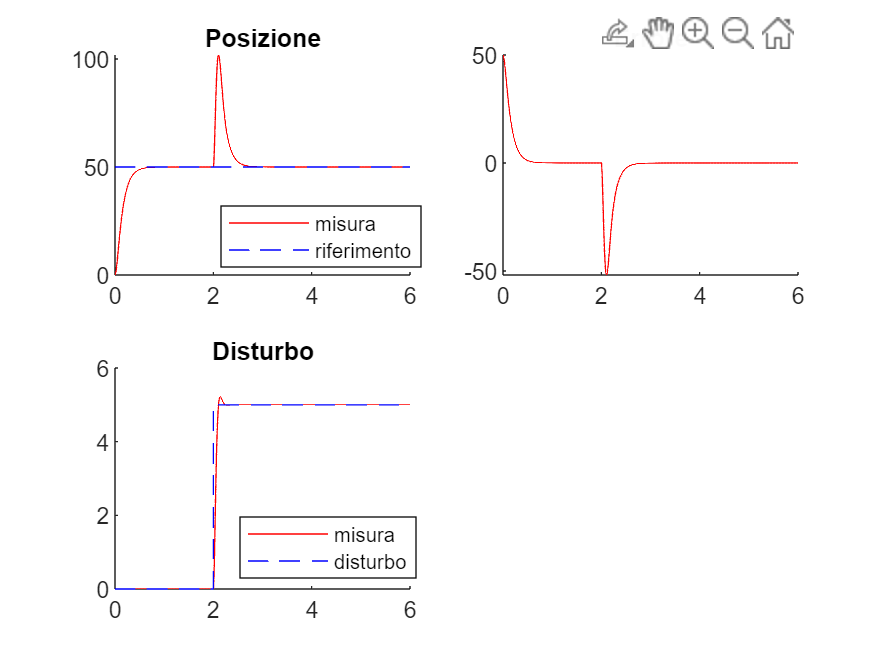

figure(1)
subplot(2, 2, 1)
hold on
title("Posizione")
plot(sim1_res.time, sim1_res.signals(1).values, "r")
plot(sim1_res.time, sim1_res.signals(2).values, "b--")
legend("misura", "riferimento")

subplot(2, 2, 2)
hold on
title("Errore")
plot(sim1_res.time, sim1_res.signals(3).values, "r")

subplot(2, 2, 3)
hold on
title("Disturbo")
plot(sim1_res.time, sim1_res.signals(5).values, "r")
plot(sim1_res.time, sim1_res.signals(4).values, "b--")
legend("misura", "disturbo")

Il controllore è privo di un polo nell'origine, ma il sistema è comunque in grado di reiettare completamente il disturbo di carico costante d.